#### Example 1

Calculate the solution to the following initial value problem using the Euler method with $h = 0.2$


$$y' = ty, \qquad t\in [0,1], \qquad y(0)=1,$$


and compare the computed solution to the exact solution which is $y = \exp\left(\frac{t^2}{2}\right)$.

% Define ODE function
f = @(t, y) t * y;

% Define IVP parameters
tspan = [0, 1];     % boundaries of the t domain
y0 = [1];           % initial value of the solution
h = 0.2;            % step length

% Calculate the solution to the IVP
[t, y] = ivp_solver(f, tspan, y0, h, @euler);

% Print table of solution values (for loop is used to group print statements)
for i = 1 : 1
    fprintf("|  t   |     y     |\n|:----:|:---------:|");
    for n = 1 : length(t)
        fprintf("\n| %4.2f | %9.6f | %9.6f | %8.2e |", t(n), y(n));
    end
end

|  t   |     y     |
|:----:|:---------:|


| 0.00 |  1.000000 | 
| 0.20 |  1.000000 | 
| 0.40 |  1.040000 | 
| 0.60 |  1.123200 | 
| 0.80 |  1.257984 | 
| 1.00 |  1.459261 | 

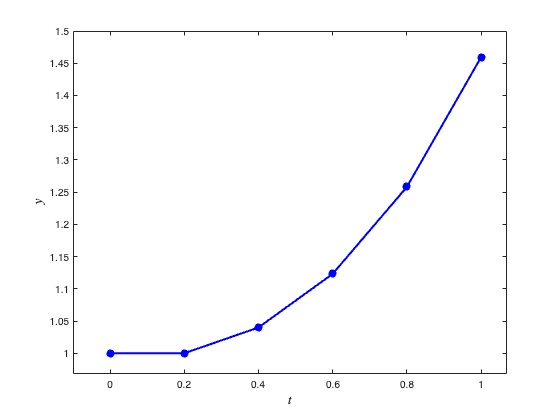

% Plot solution
plot(t, y, "b-o", LineWidth=2, MarkerFaceColor="b")
axis padded
xlabel("$t$", FontSize=14, Interpreter="latex")
ylabel("$y$", FontSize=14, Interpreter="latex")

#### Comparing errors for different step lengths

% Define ODE function and the exact solution
f = @(t, y) t * y;
exact = @(t) exp(t .^ 2 / 2);

% Define IVP parameters
tspan = [0, 1];
y0 = [1];
hvals = [0.2, 0.1, 0.05, 0.025];    % step length values

% Loop through h values and calculate solution
errors = [];
for i = 1 : 1 % use for loop to group print statements
    fprintf("Exact solution: y(1) = %1.6f", exact(1))
    fprintf(" ")
    fprintf("|   h   |  Euler   |  Error   |")
    fprintf("|:-----:|:--------:|:--------:|")
    for h = hvals
        [t, y] = ivp_solver(f, tspan, y0, h, @euler);
        errors = [errors, abs(y(end) - exact(t(end)))];
        fprintf("| %1.3f | %1.6f | %1.2e |\n", h, y(end), errors(end))
    end
end

Exact solution: y(1) = 1.648721

|   h   |  Euler   |  Error   |

|:-----:|:--------:|:--------:|

| 0.200 | 1.459261 | 1.89e-01 |
| 0.100 | 1.547110 | 1.02e-01 |
| 0.050 | 1.595942 | 5.28e-02 |
| 0.025 | 1.621801 | 2.69e-02 |


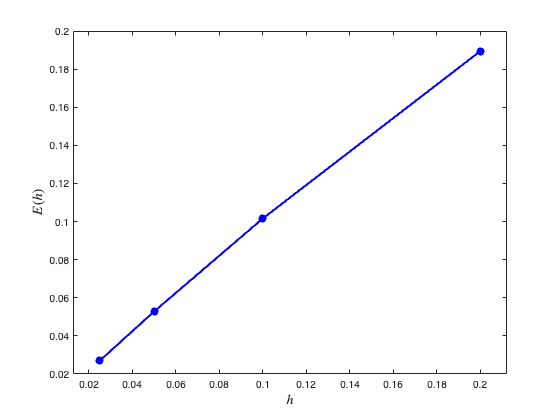

% Plot errors
plot(hvals, errors, 'b-o', LineWidth=2, MarkerFaceColor='b')
axis padded
xlabel('$h$', FontSize=14, Interpreter='latex')
ylabel('$E(h)$', FontSize=14, Interpreter='latex')

#### Example 3

The [van der Pol equation](https://en.wikipedia.org/wiki/Van_der_Pol_oscillator) is a model of a non-conservative oscillator with non-linear damping which is


$$\ddot{y} - \mu (1 - y^2) \dot{y} + y = 0,$$


where $y$ is the position of the oscillator, $\mu$ a parameter for the strength of the dampening and $\dot{y}$ and $\ddot{y}$ are the first and second-order derivatives with respect to time $t$.

Use the Euler method to calculate the solution to the van der Pol equation with $\mu=1$ over the domain $t \in [0, 20]$ with initial conditions $y(0)=2$ and $\dot{y}(0)=0$ using a step length of $h=0.1$. 

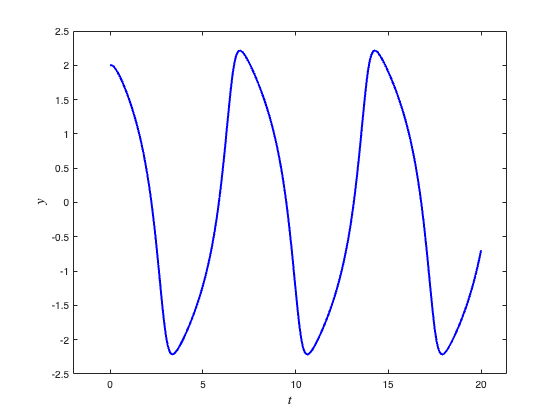

% Define ODE function (van der Pol equation)
f = @(t, y, mu) [ y(2), mu * (1 - y(1) ^ 2) * y(2) - y(1) ];

% Define IVP parameters
tspan = [0, 20];
y0 = [2, 0];
h = 0.1;
mu = 1;           % dampening parameter

% Solve the IVP using the Euler method
[t, y] = ivp_solver(@(t,y)f(t, y, mu), tspan, y0, h, @euler);

% Plot solution
plot(t, y(:, 1), 'b', LineWidth=2)
xlabel('$t$', Fontsize=14, Interpreter='latex')
ylabel('$y$', Fontsize=14, Interpreter='latex')
axis padded

## Functions

#### Single step solver

function [t, y] = ivp_solver(f, tspan, y0, h, solver, tol)

% Define t and y arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = tspan(1) : h : tspan(2);
y = zeros(nsteps + 1, length(y0));
y(1,:) = y0;

% Loop through the steps and calculate single step solver solution
for n = 1 : nsteps
    y(n+1,:) = solver(f, t(n), y(n,:), h);
end

end

#### Euler method

function ynew = euler(f, t, y, h)

ynew = y + h * f(t, y);

end